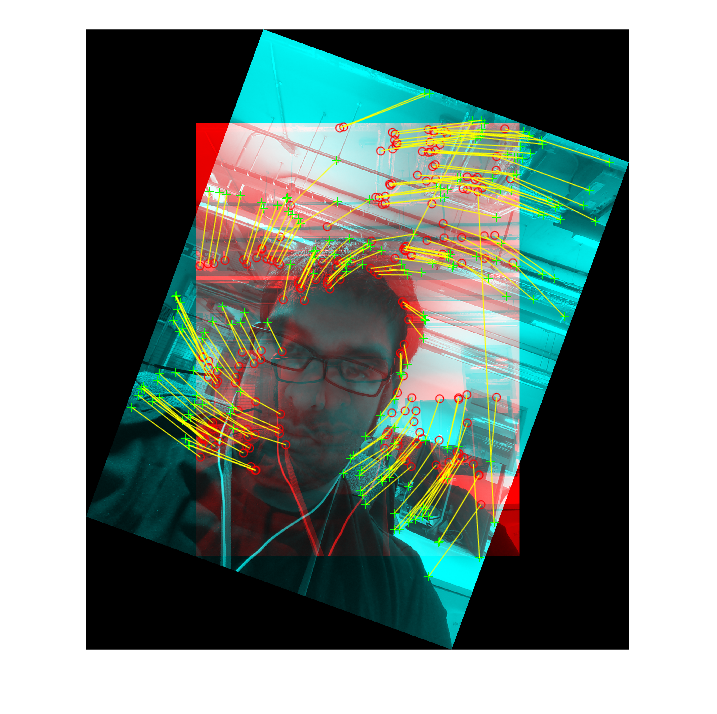

clear all;
close all;
clc;

% reads in images
pic1=imread("C:\\Users\\adbg044\\Desktop\\Visual Odometry papers\\Assets\\IMG_20191014_111003.jpg");
pic2=imresize(imrotate(pic1,-20),1.2);

% this section makes black and whit copies of the read in images
pic1BW=rgb2gray(pic1);
pic2BW=rgb2gray(pic2);

% this section detects the locations of the fetures in pixels
points1=detectMinEigenFeatures(pic1BW);
points2=detectMinEigenFeatures(pic2BW);

% this section extracts the detected fetures
[features1,valid_points1] = extractFeatures(pic1BW,points1);
[features2,valid_points2] = extractFeatures(pic2BW,points2);


% this section matches the features and stores them for easy retrival
indexPairs = matchFeatures(features1,features2);
matchedPoints1=valid_points1(indexPairs(:,1),:);
matchedPoints2=valid_points2(indexPairs(:,2),:);

% this section shows the results in a graphic window
figure("name","feature matching","numberTitle","off"); showMatchedFeatures(pic1,pic2,matchedPoints1,matchedPoints2);


% this section makes the camrea paramters
IntrinsicMatrix = [715.2699 0 0; 0 711.5281 0; 565.6995 355.3466 1];
radialDistortion = [-0.3361 0.0921]; 
cameraParams = cameraParameters('IntrinsicMatrix',IntrinsicMatrix,'RadialDistortion',radialDistortion); 

% this section gets the fundamental matrix and the essentail matrix and
% derives rotation and translation
% Also dervies the homogrpy 
F = estimateFundamentalMatrix(matchedPoints1,...
    matchedPoints2,'Method','RANSAC',...
    'NumTrials',2000,'DistanceThreshold',1e-4)

F =     0.0000    0.0000   -0.0009
   -0.0000    0.0000    0.0002
    0.0008   -0.0010    1.0000


[E,inliers] = estimateEssentialMatrix(matchedPoints1,matchedPoints2,...
 cameraParams);

inlierPoints1 = matchedPoints1(inliers);
inlierPoints2 = matchedPoints2(inliers);

homogropy = estimateGeometricTransform(matchedPoints1,matchedPoints2,'projective');

homogropy =   projective2d with properties:

                 T: [3×3 single]
    Dimensionality: 2



[relativeOrientation,relativeLocation] = relativeCameraPose(E,cameraParams,inlierPoints1,inlierPoints2);

% this section gets a depth map from the two images
